# 绘制带箭头的曲线

- [Zhihu: https://www.zhihu.com/people/1105936347](https://www.zhihu.com/people/1105936347)

- [Github: https://github.com/AFei19911012](https://github.com/AFei19911012)

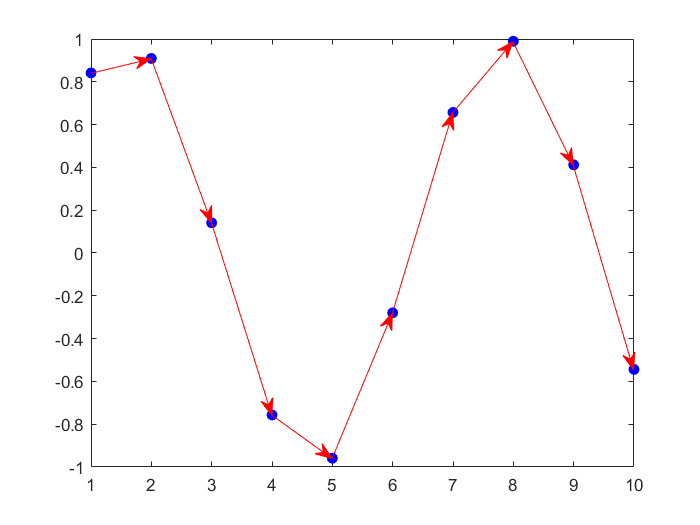

clear; clc;
x = 1:10;
y = sin(x);
plot(x, y, '.')
hold on
for i = 1:9
    PlotLineArrow(gca, [x(i), x(i + 1)], [y(i), y(i + 1)], 'b', 'r');
end
hold off

function PlotLineArrow(obj, x, y, markerColor, lineColor)
% 绘制散点图
plot(x, y, 'o', 'Color', markerColor, 'MarkerFaceColor', markerColor);
% 获取 Axes 位置
posAxes = get(obj, 'Position');
posX = posAxes(1);
posY = posAxes(2);
width = posAxes(3);
height = posAxes(4);
% 获取 Axes 范围
limX = get(obj, 'Xlim');
limY = get(obj, 'Ylim');
minX = limX(1);
maxX = limX(2);
minY = limY(1);
maxY = limY(2);
% 转换坐标
xNew = posX + (x - minX) / (maxX - minX) * width;
yNew = posY + (y - minY) / (maxY - minY) * height;
% 画箭头
annotation('arrow', xNew, yNew, 'color', lineColor);
end